experiment 1

clear
close all
load("exp1_ours.mat")
x=Exp1_4_5_AKSHAT;
figure()
plot(x,Exp1_2_5_Vout_AKSHAT,"r*","DisplayName","1.25V")
hold on
plot(x,Exp1_3_5_Vout_AKSHAT,"g*","DisplayName","1.35V")
plot(x,Exp1_4_5_Vout_AKSHAT,"b*","DisplayName","1.45V")
hold off
xlabel("V_1 Voltage (V)")
ylabel("V_2 Voltage (V)")
title("Voltage Transfer Characteristics within threshold current")
lgd=legend("Location","best")

lgd =   Legend (1.25V, 1.35V, 1.45V) with properties:

         String: {'1.25V'  '1.35V'  '1.45V'}
       Location: 'best'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.1537 0.7875 0.1464 0.1119]
          Units: 'normalized'

  Show all properties


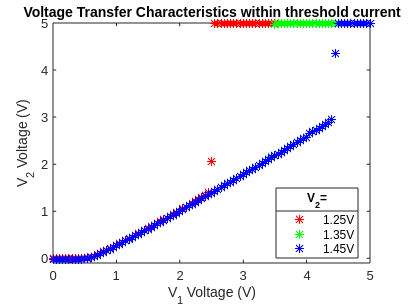

ylim([-0.1 5])
title(lgd, 'V_2=')
print("-depsc","figures/exp1_part1.eps")

above threshold

figure()
plot(x,Exp1_2_5_Vout_Strong_AKSHAT,"r*","DisplayName","1.25V")
hold on
plot(x,Exp1_3_5_Vout_Strong_AKSHAT,"g*","DisplayName","1.35V")
plot(x,Exp1_4_5_Vout_Strong_AKSHAT,"b*","DisplayName","1.45V")
hold off
xlabel("V_1 Voltage (V)")
ylabel("V_2 Voltage (V)")
title("Voltage Transfer Characteristics above threshold current")
lgd2=legend("Location","best")

lgd2 =   Legend (1.25V, 1.35V, 1.45V) with properties:

         String: {'1.25V'  '1.35V'  '1.45V'}
       Location: 'best'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.7349 0.2985 0.1464 0.1119]
          Units: 'normalized'

  Show all properties


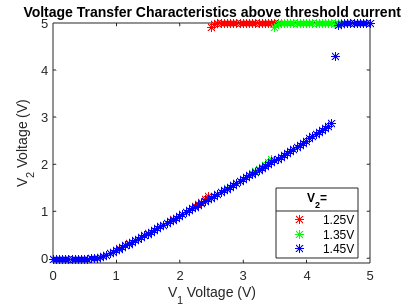

ylim([-0.1 5])
title(lgd2, 'V_2=')
print("-depsc","figures/exp1_part2.eps")

experiment 2 part 1

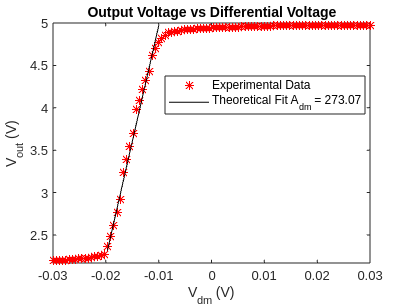

clear
close all
load("exp2_ours.mat")
figure()
plot(Exp2_Vdm_AKSHAT,Exp2_Vout_AKSHAT,"r*","DisplayName","Experimental Data")
hold on
xlabel("V_{dm} (V)")
ylabel("V_{out} (V)")
title("Output Voltage vs Differential Voltage")
legend("Location","best")

%fit line to slope
linear_idx = Exp2_Vdm_AKSHAT >= -0.02 & Exp2_Vdm_AKSHAT <= -0.01;
lin_x=Exp2_Vdm_AKSHAT(linear_idx);
lin_y=Exp2_Vout_AKSHAT(linear_idx);

[f1, l1, m1, b1, n1] = linefit(lin_x, lin_y, 5e-3);
fitline1 = m1 * lin_x + b1;

plot(lin_x, fitline1, "k", "DisplayName", sprintf("Theoretical Fit A_{dm} = %.2f", m1))
hold off
ylim([2.17 5])
print("-depsc","figures/exp2_part1.eps")

part 2

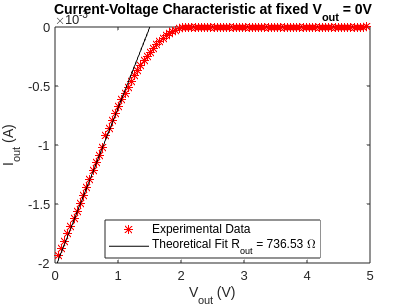

figure()
plot(Exp2_Vout_P2Sweep_AKSHAT,Exp2_Iout_AKSHAT,"r*","DisplayName","Experimental Data")
hold on
ylabel("I_{out} (A)")
xlabel("V_{out} (V)")
title("Current-Voltage Characteristic at fixed V_{out} = 0V")
legend("Location","best")
ylim([-2e-3 0])

%fit line to slope
linear_idx2 = Exp2_Vout_P2Sweep_AKSHAT >= 0 & Exp2_Vout_P2Sweep_AKSHAT <= 2;
lin_x2=Exp2_Vout_P2Sweep_AKSHAT(linear_idx2);
lin_y2=Exp2_Iout_AKSHAT(linear_idx2);

[f2, l2, m2, b2, n2] = linefit(lin_x2, lin_y2, 5e-4);
fitline2 = m2 * lin_x2 + b2;

plot(lin_x2, fitline2, "k");
legend("Experimental Data",['Theoretical Fit R_{out} = ' num2str((1/m2), '%.2f') ' \Omega'], 'Interpreter', 'tex');
hold off
print("-depsc","figures/exp2_part2.eps")

part 3

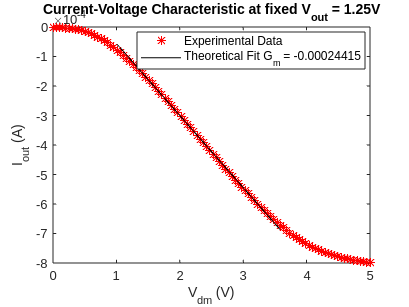

figure()
plot(Exp2_Vout_P2Sweep_AKSHAT,Exp2_Iout_P3_AKSHAT,"r*","DisplayName","Experimental Data")
hold on
ylabel("I_{out} (A)")
xlabel("V_{dm} (V)")
title("Current-Voltage Characteristic at fixed V_{out} = 1.25V")
legend("Location","best")

%fit line to slope
linear_idx3 = Exp2_Vout_P2Sweep_AKSHAT >= 1 & Exp2_Vout_P2Sweep_AKSHAT <= 3.6;
lin_x3=Exp2_Vout_P2Sweep_AKSHAT(linear_idx3);
lin_y3=Exp2_Iout_P3_AKSHAT(linear_idx3);

[f3, l3, m3, b3, n3] = linefit(lin_x3, lin_y3, 5e-4);
fitline3 = m3 * lin_x3 + b3;

plot(lin_x3, fitline3, "k");
legend("Experimental Data",['Theoretical Fit G_{m} = ' num2str(m3)], 'Interpreter', 'tex');
hold off
print("-depsc","figures/exp2_part3.eps")

experiment 3

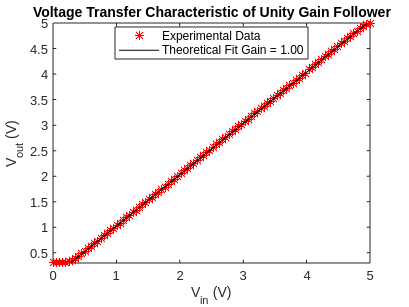

clear
close all
load("exp3_ours.mat")
plot(Exp3_Vin_AKSHAT,Exp3_Vout_AKSHAT,"r*","DisplayName","Experimental Data")
hold on
xlabel("V_{in} (V)")
ylabel("V_{out} (V)")
title("Voltage Transfer Characteristic of Unity Gain Follower")
legend("Location","best")
ylim([0.3 5])

%fit line
[f4, l4, m4, b4, n4] = linefit(Exp3_Vin_AKSHAT, Exp3_Vout_AKSHAT, 5e-4);
fitline4 = m4 * Exp3_Vin_AKSHAT + b4;

plot(Exp3_Vin_AKSHAT, fitline4, "k","DisplayName",sprintf("Theoretical Fit Gain = %.2f", m4));
legend();
hold off
print("-depsc","figures/exp3.eps")